clear all;
close all;
clc;

# HOUSEKEEPING DATA

Load the data

currentFolder = pwd;
cd('C:/Users/PC/OneDrive/Documentos/Systems_Biology_master/Internship/Internship/Data');
data = readtable("data_TPM.xlsx");
h_k_g = readtable('NM2ENSG.xlsx');
model_p = load('model.mat');
model_p = model_p.model;
model_genes_p = model_p.genes;
cd(currentFolder)

## Data preprocessing

% Colect the data needed to create the table
Ensembl_id = data(:, 1);
sampleNames = data.Properties.VariableNames(2:end); 
data_to_log = table2array(data(:, 2:end));
logged_data = log10(data_to_log + 1);%data_to_log %log10(data_to_log + 1); % Normalize the data (+1 to avoid having 0 values) 

%Create the new table with the data obtained before
log_data = [Ensembl_id, array2table(logged_data)]; % Load the data on the new table  
log_data.Properties.VariableNames(2:end) = sampleNames; % Variables names 
log_data.Properties.VariableNames{1} = 'gene'; % Change ENSEML_ID name to gene (To run findUsedGenesLevels)

% PRUNED MODEL
geneExpressionMatrix_P = [];

for i = 1: width(sampleNames)
    log_data.value = log_data{:, i + 1}; %- min(log_data{:, i + 1}); % shift minimum to 0 ¡¡ ASK MARIAN HOW HE WANT TO NORMALIZE IT!! ACTUALLY IT SAYS FPKM, SO I ALREADY HAVE IT
    [geneList, geneExpression] = findUsedGenesLevels(model_p, log_data); % Athough is just for the last sample, the genes present in the models are always the same
    geneExpressionMatrix_P = [geneExpressionMatrix_P, geneExpression'];
    log_data.value = [];
end

metabolic_genes_P = array2table(geneExpressionMatrix_P, 'RowNames', geneList, 'VariableNames', sampleNames);

% Delete the NaN values
metabolic_genes_P = rmmissing(metabolic_genes_P, 'MinNumMissing', size(metabolic_genes_P, 2)); % So we can use the local thresholding 

% Take the metabolic ENSEMBL_IDs for later
gene_names_P = metabolic_genes_P.Properties.RowNames;

## take the genes

hkg_met = model_p.genes(ismember(model_p.genes, h_k_g.converted_alias));


## Go to housekeeping enzymes

hk_enzymes = getEnzymes(model_p, hkg_met);

## Reactions

hk_reactions = hk_enzymes.rxns;

% Extract everything and put it in a vector

% Inicializar un cell array para almacenar todos los elementos
allElements = {};

% Recorrer cada celda del cell array original
for i = 1:length(hk_reactions)
    if iscell(hk_reactions{i})
        % Si la celda contiene otro cell array, extraer sus elementos
        subCell = hk_reactions{i};
        for j = 1:length(subCell)
            allElements{end+1} = subCell{j}; % Agregar cada elemento al cell array allElements
        end
    else
        % Si la celda no contiene otro cell array, agregar el elemento directamente
        allElements{end+1} = hk_reactions{i};
    end
end

% Convertir el cell array allElements en un vector si es necesario
% Si los elementos son numéricos, convertir el cell array a un vector numérico
if all(cellfun(@isnumeric, allElements))
    allElements = cell2mat(allElements);
end
hk_reactions_unique = unique(allElements)

hk_reactions_unique = 1×2188 cell array
  Columns 1 through 2047

    {'MAR00001'}    {'MAR00003'}    {'MAR00005'}    {'MAR00006'}    {'MAR00010'}    {'MAR00067'}    {'MAR00080'}    {'MAR00091'}    {'MAR00113'}    {'MAR00114'}    {'MAR00115'}    {'MAR00117'}    {'MAR00118'}    {'MAR00121'}    {'MAR00122'}    {'MAR00129'}    {'MAR00133'}    {'MAR00153'}    {'MAR00154'}    {'MAR00155'}    {'MAR00158'}    {'MAR00164'}    {'MAR00167'}    {'MAR00170'}    {'MAR00173'}    {'MAR00176'}    {'MAR00179'}    {'MAR00183'}    {'MAR00187'}    {'MAR00188'}    {'MAR00190'}    {'MAR00191'}    {'MAR00192'}    {'MAR00195'}    {'MAR00196'}    {'MAR00199'}    {'MAR00200'}    {'MAR00203'}    {'MAR00204'}    {'MAR00208'}    {'MAR00209'}    {'MAR00212'}    {'MAR00213'}    {'MAR00216'}    {'MAR00217'}    {'MAR00225'}    {'MAR00226'}    {'MAR00232'}    {'MAR00233'}    {'MAR00236'}    {'MAR00237'}    {'MAR00240'}    {'MAR00241'}    {'MAR00244'}    {'MAR00245'}    {'MAR00248'}    {'MAR00249'}    {'MAR00254'}    {'

# TEST

hkg_exp = metabolic_genes_P(ismember(metabolic_genes_P.Properties.RowNames, h_k_g.converted_alias), :)

hkg_exp = 551×48 table
                        BJ_Y1     BJ_Y2     BJ_Y3     BJ_OLD_1    BJ_OLD_2    BJ_OLD_3    IMR90_Y1    IMR90_Y2    IMR90_Y3    IMR90_O1    IMR90_O2    IMR90_O3    WI_38_Y1    WI_38_Y2    WI_38_Y3    WI_38_O1    WI_38_O2    WI_38_O3    HFF_PD16_1    HFF_PD16_2    HFF_PD16_3    HFF_PD74_1    HFF_PD74_2    HFF_PD74_3    MRC_5_PD32_1    MRC_5_PD32_2    MRC_5_PD32_3    MRC_5_PD72_1    MRC_5_PD72_2    MRC_5_PD72_3    HFF_PD26_1    HFF_PD26_2

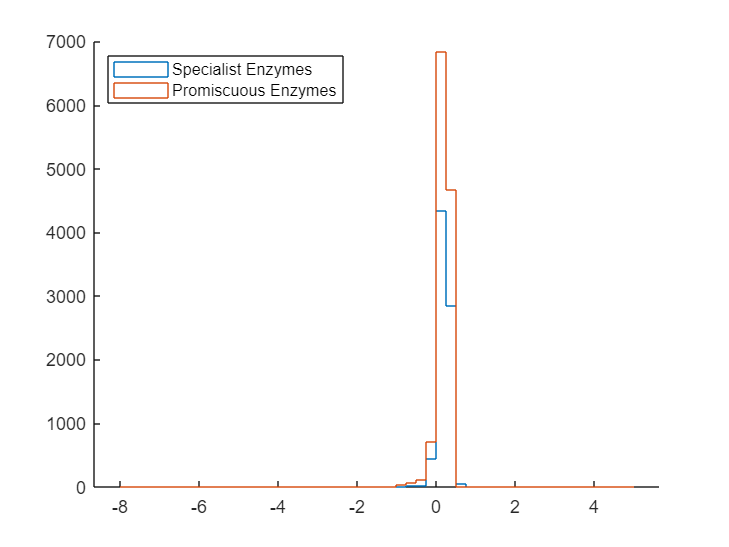

enzymeData = struct with fields:
    enzyme: {2489×1 cell}
     value: [2489×48 double]
      rxns: {2489×1 cell}
    Tissue: {48×1 cell}



%Ensuring that the first colum is names 'gene' 
data_met = hkg_exp;
data_met.gene = data_met.Properties.RowNames;
columnNames = ['gene', data_met.Properties.VariableNames];
data_met = data_met(:, columnNames);
data_met.gene_1 = [];
data_met.Properties.RowNames = {};
%Although this is not documented clearly, standep will perform a log10 on
%the expression data. To ensure that this does not introduce negative
%numbers we add 1 everywhere.
datalog10 = data_met;
datalog10{:,2:end} = datalog10{:, 2:end};%(datalog10{:,2:end}+1)

%Standep requires a very specific pre-processing for the inputs!
%1st, the RNA data structure
rnaData = struct();
rnaData.gene = data_met.gene;
rnaData.value = table2array(data_met(:,2:end));
rnaData.valuebyTissue = table2array(data_met(:,2:end));
rnaData.Tissue = data.Properties.VariableNames(2:end)';





modelData = getModelData(rnaData,model_p);

spec = getSpecialistEnzymes(model_p);  
prom = getPromEnzymes(model_p);

enzymeData = comparePromiscuousSpecific(spec,prom,modelData)

% Suponiendo que enzymeData es la estructura original
% y que contiene los campos enzyme, value, rxns y Tissue

% Paso 1: Identificar las filas que tienen todos sus elementos iguales a 0 en value
rowsToRemove = all(enzymeData.value == 0, 2);

% Paso 2: Crear una nueva estructura sin las filas y elementos correspondientes
newEnzymeData.enzyme = enzymeData.enzyme(~rowsToRemove);
newEnzymeData.value = enzymeData.value(~rowsToRemove, :);
newEnzymeData.rxns = enzymeData.rxns(~rowsToRemove);
newEnzymeData.Tissue = enzymeData.Tissue; % Tissue permanece igual

% Mostrar la nueva estructura para verificar
disp(newEnzymeData);

    enzyme: {420×1 cell}
     value: [420×48 double]
      rxns: {420×1 cell}
    Tissue: {48×1 cell}




hk_reactions = newEnzymeData.rxns;

% Extract everything and put it in a vector

% Inicializar un cell array para almacenar todos los elementos
allElements = {};

% Recorrer cada celda del cell array original
for i = 1:length(hk_reactions)
    if iscell(hk_reactions{i})
        % Si la celda contiene otro cell array, extraer sus elementos
        subCell = hk_reactions{i};
        for j = 1:length(subCell)
            allElements{end+1} = subCell{j}; % Agregar cada elemento al cell array allElements
        end
    else
        % Si la celda no contiene otro cell array, agregar el elemento directamente
        allElements{end+1} = hk_reactions{i};
    end
end

% Convertir el cell array allElements en un vector si es necesario
% Si los elementos son numéricos, convertir el cell array a un vector numérico
if all(cellfun(@isnumeric, allElements))
    allElements = cell2mat(allElements);
end
hk_reactions_unique = unique(allElements)

hk_reactions_unique = 1×1820 cell array
    {'MAR00001'}    {'MAR00003'}    {'MAR00005'}    {'MAR00006'}    {'MAR00010'}    {'MAR00067'}    {'MAR00091'}    {'MAR00113'}    {'MAR00114'}    {'MAR00115'}    {'MAR00117'}    {'MAR00118'}    {'MAR00121'}    {'MAR00122'}    {'MAR00129'}    {'MAR00133'}    {'MAR00153'}    {'MAR00154'}    {'MAR00155'}    {'MAR00158'}    {'MAR00164'}    {'MAR00167'}    {'MAR00170'}    {'MAR00173'}    {'MAR00176'}    {'MAR00179'}    {'MAR00183'}    {'MAR00187'}    {'MAR00188'}    {'MAR00190'}    {'MAR00191'}    {'MAR00192'}    {'MAR00195'}    {'MAR00196'}    {'MAR00199'}    {'MAR00200'}    {'MAR00203'}    {'MAR00204'}    {'MAR00208'}    {'MAR00209'}    {'MAR00212'}    {'MAR00213'}    {'MAR00216'}    {'MAR00217'}    {'MAR00225'}    {'MAR00226'}    {'MAR00232'}    {'MAR00233'}    {'MAR00236'}    {'MAR00237'}    {'MAR00240'}    {'MAR00241'}    {'MAR00244'}    {'MAR00245'}    {'MAR00248'}    {'MAR00249'}    {'MAR00254'}    {'MAR00255'}    {'MAR00258'}    {'MAR00259'}